x0 = dlarray([-1, 2]);
[fval, gradval] = dlfeval(@rosenbrock, x0)

fval =   1×1 dlarray

   104


gradval =   1×2 dlarray

   396   200


[X1 X2] = meshgrid(linspace(0,1,10));
X1 = dlarray(X1(:));
X2 = dlarray(X2(:));
Y = dlarray(zeros(size(X1)));
DYDX1 = Y;
DYDX2 = Y;

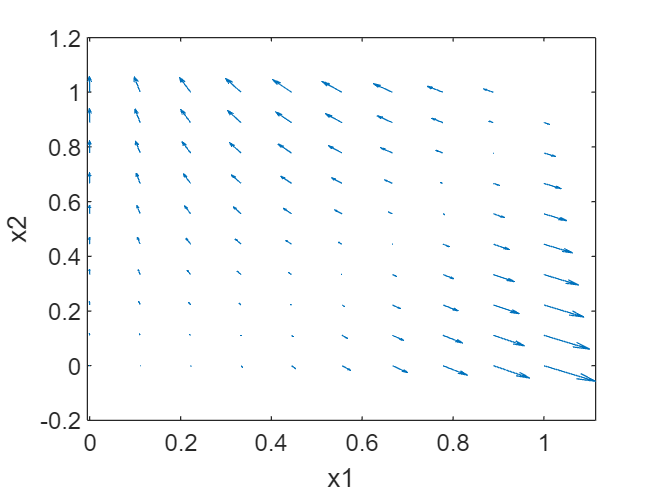

for i = 1:length(X1)
    [Y(i),DYDX1(i),DYDX2(i)] = dlfeval(@rosenbrock2,X1(i),X2(i));
end
quiver(extractdata(X1),extractdata(X2),extractdata(DYDX1),extractdata(DYDX2))
xlabel('x1')
ylabel('x2')

Define Rosenbrock's function as a function of a vector x

function [y, dydx] = rosenbrock(x)
    y = 100*(x(2) - x(1).^2).^2 + (1-x(1)).^2;
    dydx = dlgradient(y,x);
end

Define Rosenbrock's function as a function of two inputs, x1 and x2

function [y, dydx1, dydx2] = rosenbrock2(x1,x2)
    y = 100*(x2 - x1.^2).^2 + (1-x1).^2;
    [dydx1, dydx2] = dlgradient(y, x1, x2);
end
